x = [6 8];
norm(x)

ans = 10

벡터 크기 계산

x1 = x/norm(x)

x1 =     0.6000    0.8000


벡터 정규화(벡터를 크기로 나눔)

u = [2 6 5]

u =      2     6     5


v = [-4 3 -2]

v =     -4     3    -2


dot(u,v)

ans = 0

theta = acos(dot(u,v)/norm(u)/norm(v))

theta = 1.5708

degree = theta/pi*180

degree = 90

벡터의 내적

cross(u,v)

ans =    -27   -16    30


벡터의 외적

x = [-3 -2 2]; y = [-2 2 3]; z = [2 -4 3];
T = dot(cross(x,y),z)

T = -70

V = abs(T)

V = 70

T : 벡터의 스칼라 삼중적

V : 부피

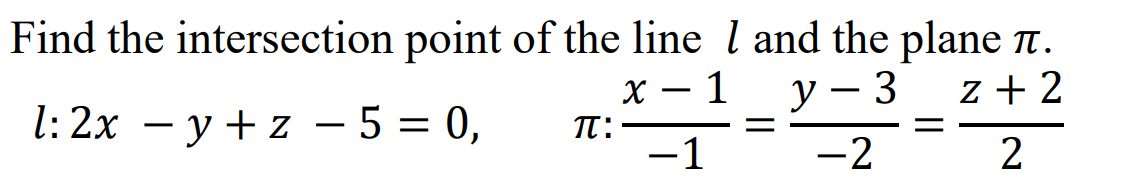

syms x y z % symbolic 변수로 처리
t = sym('t')

$$t = t$$

x = -t+1; y = -2*t+3; z = 2*t-2;
solve(2*x-y+z-5==0, t)

$$ans = 4$$

u1 = [-5 1 2]; u2 = [3 -7 1]; u3 = [-2 -6 3];
A = [u1;u2;u3]

A =     -5     1     2
     3    -7     1
    -2    -6     3


rank(A) % rank < 3 -> 일차독립

ans = 2

det(A)

ans = 0

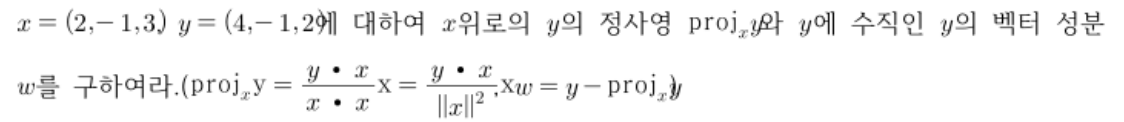

x = [2 -1 3]; y = [4 -1 2]

y =      4    -1     2


proj = dot(y,x)/dot(x,x)*x

proj =     2.1429   -1.0714    3.2143


w = y-proj

w =     1.8571    0.0714   -1.2143


u = dot([3,-1,2],[1,3,-2])-6

u = -10

v = norm([1,3,-2])

v = 3.7417

d = abs(u)/v

d = 2.6726

syms x y z
S = solve(x+y+2*z==9,2*x+4*y-3*z==1,3*x+6*y-5*z==0)

S = 다음 필드를 포함한 struct :
    x: 1
    y: 2
    z: 3


s = [S.x S.y S.z]

$$s = \left(\begin{array}{ccc} 1 & 2 & 3 \end{array}\right)$$

A = [1 1 2; 2 4 -3; 3 6 -5]

A =      1     1     2
     2     4    -3
     3     6    -5


X = [9; 1; 0]

X =      9
     1
     0


%AX = [A,X] % 붙임행렬 생성

AX =      1     1     2     9
     2     4    -3     1
     3     6    -5     0


스크립트 rref을(를) 함수로 실행하는 것은 지원되지 않습니다.
C:\Users\i4u11\Desktop\study\Career\recording_study\Linear_Algebra\rref.m

[A,X] = rref(AX)
R

RREF 이용

clear; clc;
A = [2 4 6;2 -1 1;3 0 -1];
x = [18; 8; 3]
Ax = [A, x]
rref(Ax)

a = [1 3 -2 0 2 0;2 6 -5 -2 4 -3;0 0 5 10 0 15;2 6 0 8 4 18]
X = [0;-1;5;6]
aX = [a,X]
rref(aX)
linsolve(aX)

Matrix operation

A = [1 1 -4;-2 1 3]; B = [0 1 4;-1 3 1]; C=[1 1; 2 2];
A+B
2*A
-1*C

Matrix Multiplication

A = [1 2 -1; 3 1 0]; B = [-2 1; 0 -3; 2 1];
A * B
A = [1 2;-1 3; 1 0]
A.*B %.을 붙이면 성분 별 연산
A./B % 성분끼리 나눗셈
A.^B % 성분끼리 제곱

&

A = [1 -2 3;4 5 0];
B = [1 2 -4;3 -1 2;0 5 3];

AT = A'
BT = B'

C = rand(4,4)
C'*C

C = inv([1 4 3;2 5 6;0 0 0])
%rank(C)
D = inv(C)

if inv(D) ~= Inf %행렬식이 0이라면
    disp('no inverse')  
else
    disp('exist inverse') % 0이 아니면 역행렬 존재
end

A = [1 -1 2; -1 0 2;-6 4 11];
I = [1 0 0;0 1 0; 0 0 1];
AI = [A, I]
%AI_rref = rref(AI)
%A_inv = AI_rref(1:3, 4:6) %역행렬 = 원래 단위행렬의 위치의 행렬

backslash operator

A = [1 2 3;2 5 3;1 0 8]; b = [1; 3; -1];
A\b
inv(A)*b

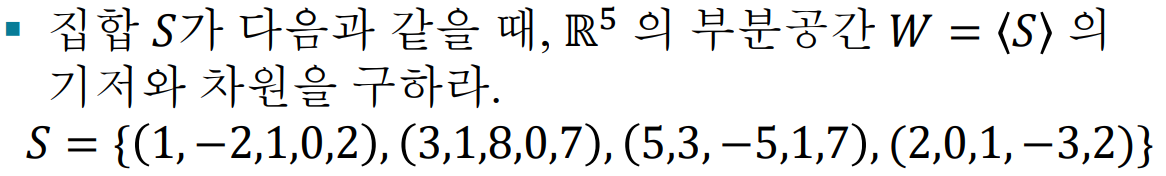

format rat
A = [1 -2 1 0 2;3 1 8 0 7;5 3 -5 1 7;2 0 1 -3 2];
% rref(A)
% -> 4차원, rref의 각 행이 basis

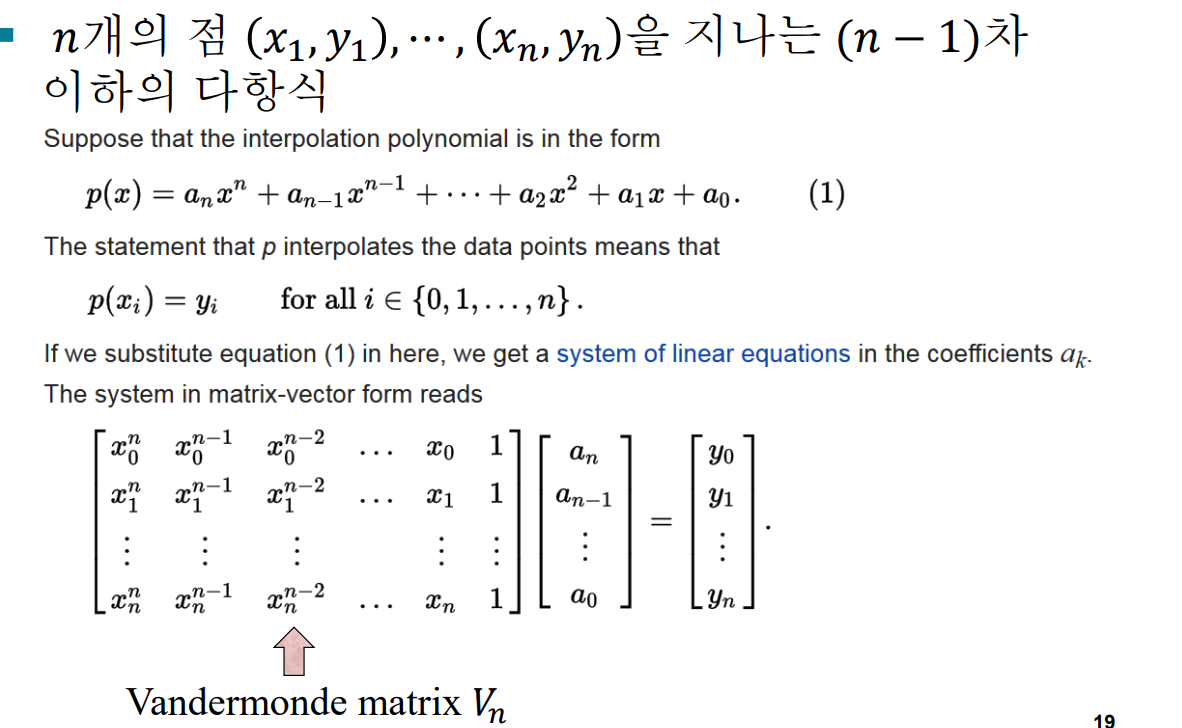

X = [-1 0 1 3];
A = vander(X)
B = [3 4 2 6]';
C = inv(A)*B
ezplot('17/24*x^3-3/2*x^2-29/24*x+4=y')

LU decomposition

A = [1 2 3;4 5 6;7 8 9];
[L1, U1] = lu(A)         % 내장함수 이용  
[L1, U1] = lu_gauss(A)   % 행교환 없는 LU분해(lu_gauss.m 실행)

A = [2 4 -2;4 9 -3;-2 -3 7];
[L U P] = lu(A)
[L U] = lu_gauss(A)